% Load image
A = imread('fuecoco.png');
A = A(122:256,78:178,:);

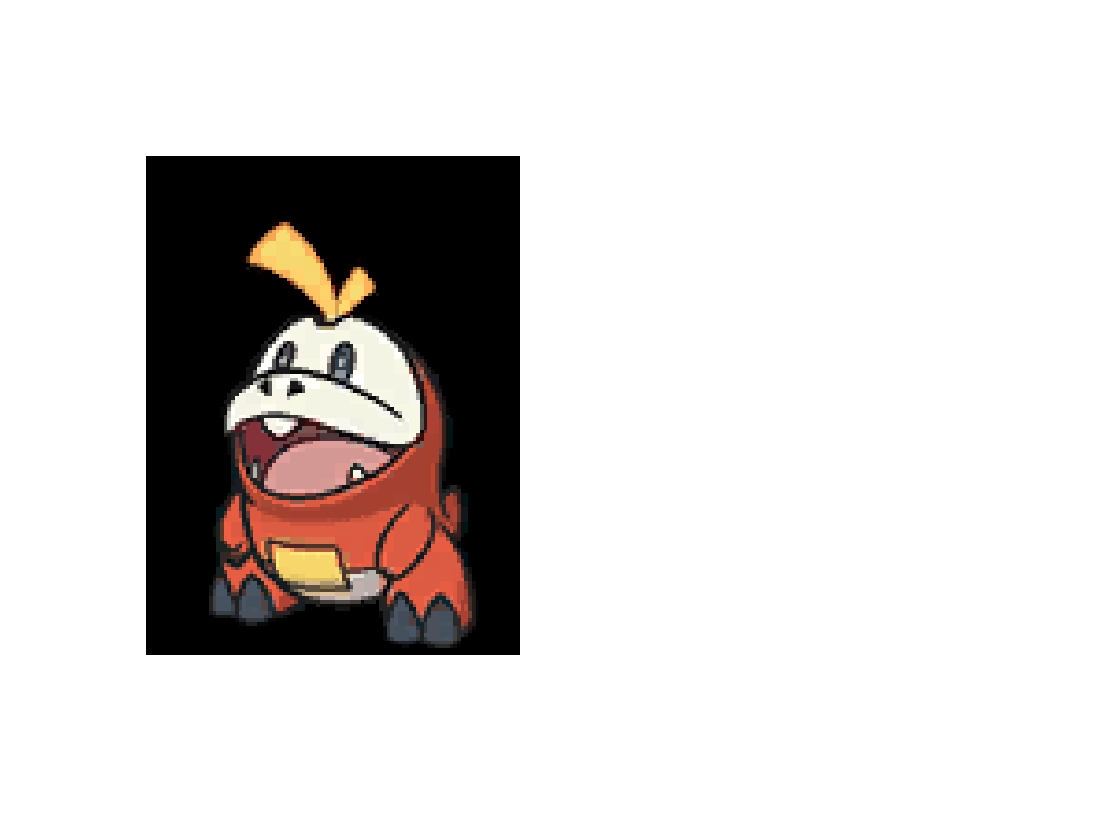

subplot(1,2,1), imshow(A)

[n,m,l] = size(A);
NM = n*m;

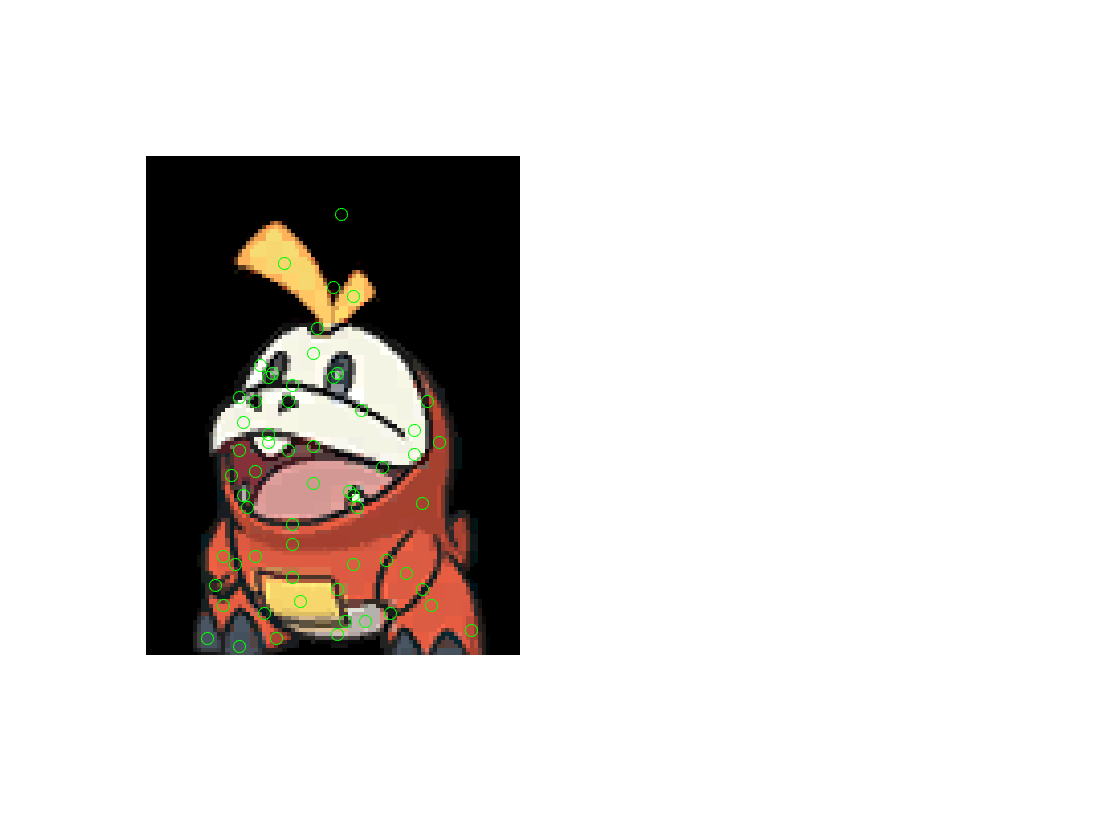

% Define labels
L = [1, 2, 3, 4, 5, 6]; % 1 - red, 2 - yellow, 3 - black, 4 - white, 5 - pink, 6 - dark red
% Define seeds
S = [113, 76, 1; 101, 25, 1; 113, 25, 1; 105, 70, 1; 103, 57, 1; 101, 33, 1; 
    29, 40, 2; 37, 57, 2; 112, 44, 2; 
    17, 54, 3; 123, 29, 3; 128, 70, 3; 63, 75, 3; 57, 36, 3; 57, 52, 3; 63, 41, 3; 63, 33, 3; 71, 36, 3; 89, 31, 3; 89, 58, 3; 103, 28, 3; 117, 55, 3; 121, 21, 3; 108, 23, 3; 115, 35, 3; 106, 42, 3; 109, 53, 3; 131, 57, 3; 115, 66, 3; 102, 65, 3; 109, 74, 3; 93, 42, 3; 85, 56, 3; 75, 41, 3; 79, 64, 3; 74, 47, 3; 62, 29, 3; 59, 42, 3; 65, 59, 3; 76, 72, 3; 45, 48, 3; 35, 52, 3; 127, 81, 3; 81, 27, 3; 
    51, 47, 4; 56, 37, 4; 70, 72, 4; 68, 30, 4; 56, 53, 4; 73, 36, 4; 86, 30, 4; 86, 57, 4; 117, 60, 4; 120, 53, 4; 54, 34, 4; 
    83, 47, 5;
    121, 38, 6; 119, 86, 3; 98, 42, 6; 88, 74, 6; 73, 78, 6; 75, 29, 6; 80, 33, 6];
c = [A(113, 76, :); A(29, 40, :); A(17, 54, :); A(51, 47, :); A(83, 47, :); A(121, 38, :)]; c = reshape(c,6,3); c = double(c);

hold on
plot(S(:,2), S(:,1), 'o', 'Color', 'green')
hold off

T = 5000; % Number of steps
img = double(A);

tic
W = sparse(calculate_weights(img,150));
toc

Elapsed time is 1.134367 seconds.


tic
H = construct_hamiltonian(W, 0.001);
toc

Elapsed time is 1.559568 seconds.


tic
for i = 1:numel(L) % use parfor if available
    sprintf("Working with label: %d", i)
    subset = seeds_subset(S,L(i));
    subset_length = size(subset,1);
    A_sub = zeros(NM,1);
    for p = 1:subset_length
        if subset(p,2) + m*(subset(p,1)-1) > numel(A)
            p
            subset(p,2) + m*(subset(p,1)-1)
        end
        A_sub( subset(p,2) + m*(subset(p,1)-1) ) = 1;
    end
    state = 1/sqrt(subset_length) * sparse(A_sub);
    sprintf("The norm of our intial state vector is: %d", dot(full(state), full(state)))
    state = update_state(-T*1i, H, state);
    D(:,i) = retrieve_position(state);
    % sprintf("After %d steps, the norm is: %d", T, dot(full(state), full(state)))
    % LD(:,i) = 1/T * sum(D,2);
    % sprintf("Limiting distribution of label %d found", i)
end

ans = "Working with label: 1"

ans = "The norm of our intial state vector is: 1.000000e+00"

ans = "Working with label: 2"

ans = "The norm of our intial state vector is: 1.000000e+00"

ans = "Working with label: 3"

ans = "The norm of our intial state vector is: 1"

ans = "Working with label: 4"

ans = "The norm of our intial state vector is: 1"

ans = "Working with label: 5"

ans = "The norm of our intial state vector is: 1"

ans = "Working with label: 6"

ans = "The norm of our intial state vector is: 1.000000e+00"

toc

Elapsed time is 1.239580 seconds.


B_os = zeros(n,m,3);
for i = 1:n
    for j = 1:m
        k = find_seed(D,i,j,m);
        B_os(i,j,:) = c(k,:);
    end
end

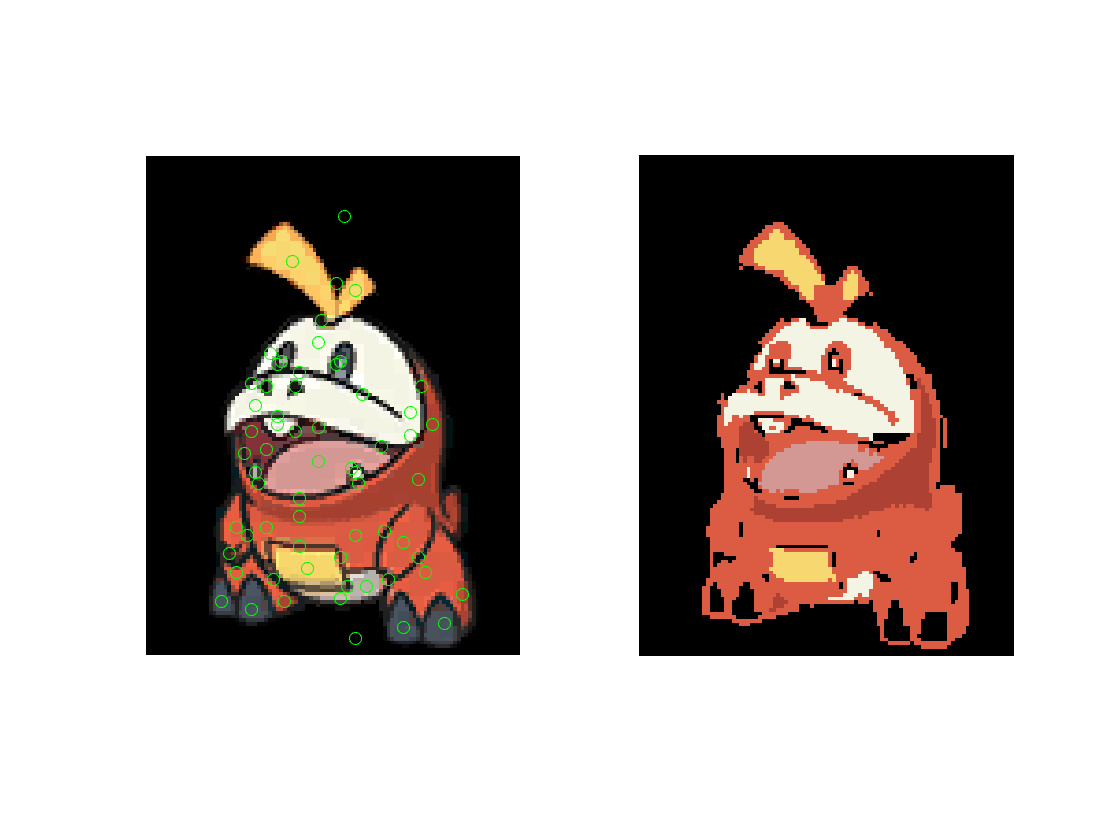

B_os = uint8(B_os);
subplot(1,2,2), imshow(B_os)